close all
clear variables
tic()

file_name="data.mat";
epoch_duration = 30;
features = ["Delta", "Theta", "Alpha", "Beta", "Gamma", "Total"];
freq_ranges = {
    [1, 4];
    [4, 8];
    [8, 12];
    [12, 30];
    [30, 50];
    [1, 50];
};

## Data acquisition

[EEG, fs, t] = data_acquisition(file_name);

## Plotting the EEG

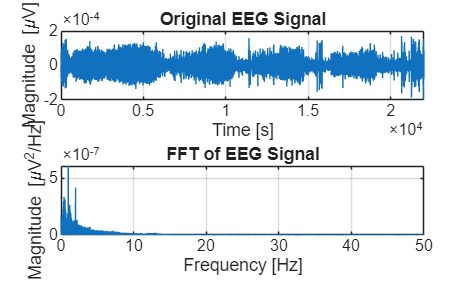

plot_eeg_fft(t, EEG, fs);

## Computing filters for 1HZ and 2HZ noise

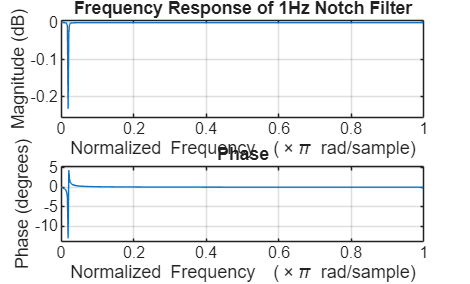

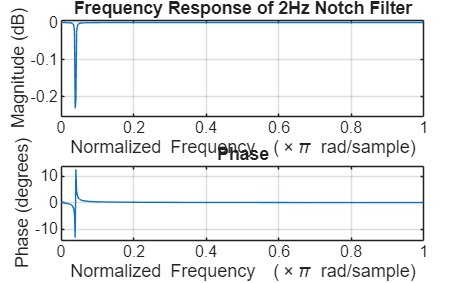

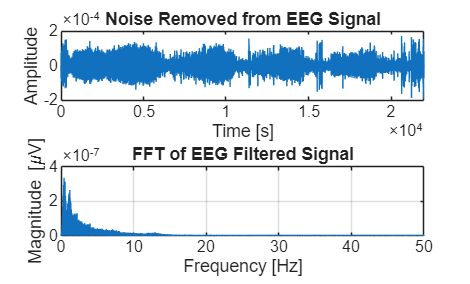

[EEG_filtered]=double_notch_filter(fs, EEG, t,1,2); %fcut1 fcut2

## Dividing the original signal in different epochs

EEG_seg = eeg_segmentation(fs, EEG_filtered, epoch_duration); %epoch duration

## Computing the PSD (of EACH EPOCH)

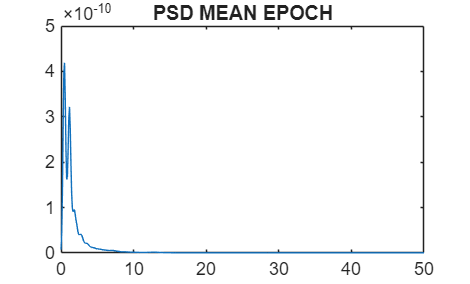

window_dim=5;
[PSD_EEG, f3] = psd_calc(EEG_seg, fs, window_dim); %window dimension

## Features Struct Definition

[features_struct] = struct_def(features);

## Power Calculation

[features_struct,psd_struct,struct_len] = power_calc(PSD_EEG, features, f3, features_struct, freq_ranges);

## Percentage Calculation

features_perc = perc_calc(features, PSD_EEG, features_struct);

## Mean and Standard Deviation Computing for linear analysis

features_mean = struct();
features_std = struct();

for i=1:length(features)
    features_mean.(features(i)) = mean(features_perc.(features(i)));
    features_std.(features(i))=std(features_perc.(features(i)));

end

## Sample Entropy and Approximate Entropy determination for non-linear analysis

m = 2; % Length of the pattern
r = 0.2; % Tolerance

SampEn_values = zeros(1, size(EEG_seg, 1));
ApEn_values = zeros(1, size(EEG_seg, 1));

for epoch = 1:size(EEG_seg, 1)
    SampEn_values(epoch) = sample_entropy(EEG_seg(epoch, :), m, r, 'chebychev');
    ApEn_values(epoch) = approximateEntropy(EEG_seg(epoch,:));
end

## Calculating Power of each Wave

sleep_stage=zeros(1,struct_len);

for i = 1:struct_len
    if (features_perc.Alpha(i) > features_mean.Alpha + features_std.Alpha) && (features_perc.Beta(i) > features_mean.Beta)
        sleep_stage(i) = 0; % Awake
    elseif (features_perc.Delta(i) > features_mean.Delta - features_std.Delta)
        sleep_stage(i) = 2; % NREM
    elseif (features_perc.Beta(i) > features_mean.Beta - features_std.Beta) && (features_perc.Theta(i) > features_mean.Theta)
        sleep_stage(i) = 1; % REM
    end
end

## Sleep Stages Percentages calculation

sleep_stage_perc=zeros(1,3);

for i= 1:length(sleep_stage)
    if sleep_stage(i)==0
        sleep_stage_perc(1)=sleep_stage_perc(1)+1;
    elseif sleep_stage(i)==1
        sleep_stage_perc(2)=sleep_stage_perc(2)+1;
    else
        sleep_stage_perc(3)=sleep_stage_perc(3)+1;
    end
end

## Smoothing the Hypnogram

min_duration=6; % NUMBER OF EPOCH THAT HAVE TO BE EQUALS
filtered_sleep_stage=filtered_sleep_stages_def(sleep_stage, min_duration);

sleep_stage_perc=zeros(1,3);

for i= 1:length(filtered_sleep_stage)
    if filtered_sleep_stage(i)==0
        sleep_stage_perc(1)=sleep_stage_perc(1)+1;
    elseif filtered_sleep_stage(i)==1
        sleep_stage_perc(2)=sleep_stage_perc(2)+1;
    else
        sleep_stage_perc(3)=sleep_stage_perc(3)+1;
    end
end

sleep_stage_perc=sleep_stage_perc/length(sleep_stage);

## Plotting the hypnogram

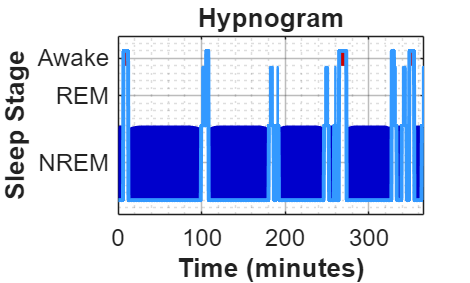

t_min=hypnogram(filtered_sleep_stage,epoch_duration);

## Comparison between the Sample Entropy and the computed hypnogram

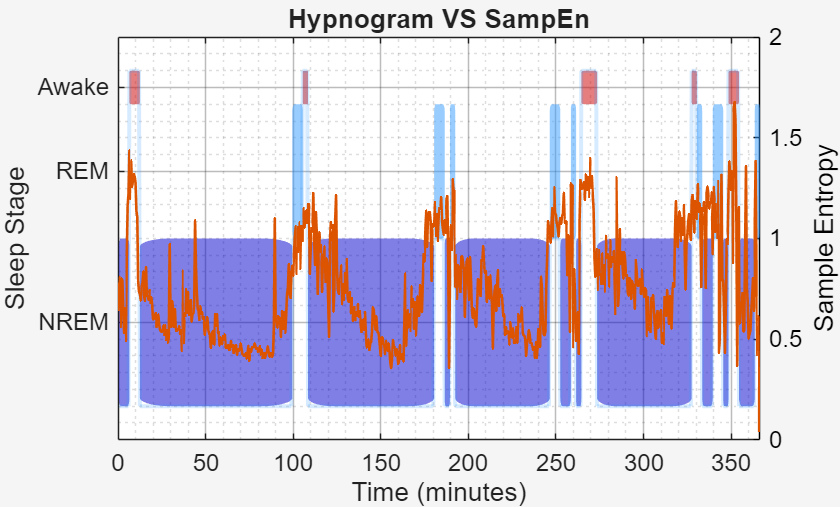

fig1 = figure(6);

fig2 = copyobj(fig1, 0);


axes_in_fig2 = findall(fig2, 'Type', 'axes'); 
patch_in_fig2 = findall(axes_in_fig2, 'Type', 'patch');
rectangles_in_fig2 = findall(axes_in_fig2, 'Type', 'rectangle');
set(patch_in_fig2, 'FaceAlpha', 0.5);
set(rectangles_in_fig2, 'FaceAlpha', 0.5)

hold on 
yyaxis right

plot([0,0,t_min],SampEn_values, 'LineWidth', 1.3)
ax = gca;
ax.YAxis(2).Color = 'black';
xlim tight

ylabel("Sample Entropy", "Color",[0 0 0])
title("Hypnogram VS SampEn");